# Continuous braking Thermal analysis of brake disc

This script approximates the temperature of the brake rotor after "N" applications of the brakes

Author: Luis Daniel Medina Querecuto

luisdamed@gmail.com

Date: 17/11/2019

References: 

[1] Incropera, F.,De Witt, David. "*Fundamentals of Heat and Mass Transfer, 6th Edition". *Prettice Hall. **ISBN-13:** 978-0470055540

[2] R. Limpert, Brake Design and Safety, Warrendale, PA.: Society of Automotive Engineers, Inc., 1999. **ISBN-13:** 978-1560919155

[3] B. Latour, P. Bouvier and S. Harmand, "Convective Heat Transfer on a Rotating Disk With Transverse Air Crossflow," *Journal of Heat Transfer, *vol. 133, pp. 021702-1 -10, 2011. DOI: 10.1115/1.4002603

 clc, close all

## Input data

Disc_data;

V_disc = 5.4432e-05

w_pad = 0.0498

S_p = 0.0015

t_pad = 0.0040

S_d = 0.0163

load Air_props.mat
m= 290 %car mass in kg

m = 290

I=0.3546 %Moment of inertia of the rotating parts on the wheel [kg/m2]

I = 0.3546

Vi= 60/3.6 %Initial Vehicle Speed [m/s]

Vi = 16.6667

Vf=45/3.6 %Final Vehicle Speed [m/s]

Vf = 12.5000

V_mean=(Vf+Vi)/2

V_mean = 14.5833

R_wheel=0.235 %Wheel Radius [m]

R_wheel = 0.2350

omegai=Vi/R_wheel %initial wheel angular speed [rad/s]

omegai = 70.9220

omegaf=Vf/R_wheel %Final wheel angular speed [rad/s]

omegaf = 53.1915

Decel_avg=0.7*9.81 %Average deceleration in [m/s^2]

Decel_avg = 6.8670

Brake_bias=0.5 %brake distribution on the axle of the study

Brake_bias = 0.5000

tstop= (Vi-Vf)/Decel_avg %Duration of the braking maneuver [s]

tstop = 0.6068

dstop=(Vi^2-Vf^2)/(2*Decel_avg) %distance covered during braking in meters

dstop = 8.8487

tcool=5 %Cooling time between braking maneuvers [s]

tcool = 5

materials=6 %Define the number fo materials to compare. Uses Mat_properties.m

materials = 6

n= 100  %number of braking maneuvers to simulate

n = 100

Cx=1.12; %Aerodynamic drag
S_car=1; %Front surface area of the car in m2

### Average power dissipated during the single braking maneuver


$$E_k =\frac{1}{2}{\textrm{Bias}}_{\textrm{front}\;} \left(\frac{1}{2}m\left(V_i^2 -V_{f\;}^2 \right)-\frac{1}{2}\rho {\;}_{\textrm{air}\;} C_{x\;} {\textrm{SV}}_{\textrm{avg}}^2 d_{\textrm{stop}} \right)+\frac{1}{2}I\left(\omega {\;}_i^2 -\omega {\;}_f^2 \right)$$


Kinetic linear and rotational energies minus approximately the average energy dissipated by the aerodynamic drag.

Ef=0.5*Brake_bias*((m/2)*(Vi^2-Vf^2)-0.5*1.16*Cx*S_car*((Vi+Vf)/2)^2*dstop)+(I/2)*...
(omegai^2-omegaf^2) 

Ef = 4.4899e+03

Average power dissipated during the braking maneuver [W]

P_avgF=Ef/tstop; 

### Pre-allocate variables

T_disc=zeros(1,n);
T_film=zeros(1,n);
rho_air_f=zeros(1,n);
mu_air_f=zeros(1,n);
Cp_air_f=zeros(1,n);
k_air_f=zeros(1,n);
Re_f=zeros(1,n);
Pr_f=zeros(1,n);
h_conv=zeros(1,n);
T_disc_mat=zeros(materials,n);

### Evaluate the Temperature veriation for different materials

for mat=1:materials

### Thermal  cycle start

    for i=1:n
        if i>1 && mod(i, 2)==0
        T_disc(i)=T_disc(i-1)-Dtcool;
        elseif mod(i, 2)==1 %Do this only for odd numbers of i
            if i==1
                %Input brake disc temperature [K].
                % Assumed or estimated value
                T_disc(i)=60+273.15;  
                
            else
                BixFo=h_conv*A_total*tcool/(rho_metal*V_disc*Cp_metal);
                
                %Temperature of the rotor at the begining og the new cycle
                T_disc(i)=T_air+(1-exp(-i*BixFo))*DT_f/(1-exp(-BixFo)); 
            end
            %Air Temperature [K]
            T_air=22+273.15; 
            
            %Film Temperature [K]
            T_film(i)=(T_air+T_disc(i))/2; 

#### Air Properties vs Temperature  

            %Air density at film temperature [kg/m3]
            rho_air_f(i) = interp1(Air_props.Temp,Air_props.Density,...
                T_film(i)-273.15); 
            
            %Air Dynamic viscosity at film temperature [kg/ms]
            mu_air_f(i) = interp1(Air_props.Temp,Air_props.Dyn_Visc,...
                T_film(i)-273.15); 
            
            %Air Specific heat at film temperature [J/kgK]
            Cp_air_f(i) = interp1(Air_props.Temp,Air_props.Spec_Heat,...
                T_film(i)-273.15); 
            
            %Air Thermal conductivity at film temperature [W/mK]
            k_air_f(i) = interp1(Air_props.Temp,Air_props.Conductivity,...
                T_film(i)-273.15); 

#### Reynolds number for different flow conditions 

            %Reynolds number evaluated at film temperature
            Re_f(i)=(V_mean*r_disc*2*rho_air_f(i))/mu_air_f(i);    
            
            %Prandtl number evaluated at film temperature
            Pr_f(i)=mu_air_f(i) *Cp_air_f(i)/k_air_f(i);             

#### Heat transfer coefficient 

This expression is mentioned in reference [1]. It was determined experimentally on disc brakes for light trucks, but can also be used in other applications to a certain extent. Verified with Convection_coefficients.mlx script and  the results showed good correlation with CFD analyses at 60 km/h


$$h=0\ldotp 04\left(\frac{k_{\textrm{air}} }{D}\right){\textrm{Re}}^{0\ldotp 8}$$


             h_conv(i)=0.04*(k_air_f(i)/(2*r_disc))*Re_f(i)^0.8;

#### Load  the material properties library

             Mat_properties; 

#### Biot number verification

Assuming an uniform temperature distribution on the whole volume of the disc (Lumper mass assumption). We determine the Biot number,  to make sure that the Lumped system model is valid for the thermal conditions of the rotor. 

             A_total=A_edge+2*A_side+A_holes; %Total surface area of the disc
             
             %Biot number. The following equations are valid only for Bi<0.1
             Bi=h_conv*(V_disc/(A_total))/k_metal;  
                if Bi>0.09999
                   error(['The Biot number must be lower than 0.1 to assume an ' ...
                       'uniform disc temperature distribution (lumped analysis)'])
                end
        

#### Heat Transfer Disc/Pad 

The factor "p" determines the portion of heat which is transferred to the rotor body during continuous braking.

                %Thermal resistance of the Brake rotor
                Rd= 1/(A_total*h_conv(i)); 
                
                %Heat convection coefficient of the pad.
                hp_conv=h_conv(i)*0.01; 
                
                %Thermal resistance of the pad
                Rp= 1/hp_conv+t_pad/(k_pad*S_p)+t_plate/(k_plate*S_p); 
                
                %Heat Partition Coefficient
                p=1/(1+Rd/Rp);
                
                %p=sqrt(k_metal*Cp_metal*rho_metal)*S_d/
                % (sqrt(k_metal*Cp_metal*rho_metal)*S_d+
                %       sqrt(k_pad*Cp_pad*rho_pad)*S_p); 

#### Calculate the temperature rise on the disc

Temperature increase of the rotor during a single stop


$$\Delta \;T=\frac{P_{\textrm{avg}} t_{\textrm{stop}} p}{\rho {\;}_{\textrm{metal}} V_{\textrm{disc}} {\textrm{Cp}}_{\textrm{metal}} }$$


            DT_f=P_avgF*tstop*p/(rho_metal*V_disc*Cp_metal); 

Cool down the disc while not braking

        %Heat dissipated by convection [W]
        H_convection=(h_conv(i)*A_total)*(T_disc(i)-T_air);
        
        %Heat dissipated by radiation [W]
        H_radiation= 5.670367*10^-8*A_total*2*(T_disc(i)-T_air)^4; 
    
        Dtcool=(-H_convection-H_radiation)*(tcool)/(rho_metal*V_disc*Cp_metal);
        end
    end
    
   T_disc_mat(mat,:)=T_disc; %Save the results from the current material cycle
end

time=linspace(0,(tstop+tcool)*n,n)

time =          0    5.6634   11.3268   16.9902   22.6536   28.3170   33.9804   39.6438   45.3072   50.9706   56.6340   62.2974   67.9608   73.6242   79.2876   84.9510   90.6144   96.2778  101.9412  107.6046  113.2680  118.9314  124.5948  130.2582  135.9216  141.5850  147.2484  152.9118  158.5752  164.2386  169.9020  175.5654  181.2288  186.8922  192.5556  198.2190  203.8824  209.5458  215.2092  220.8726  226.5360  232.1994  237.8628  243.5262  249.1896  254.8530  260.5164  266.1798  271.8432  277.5066


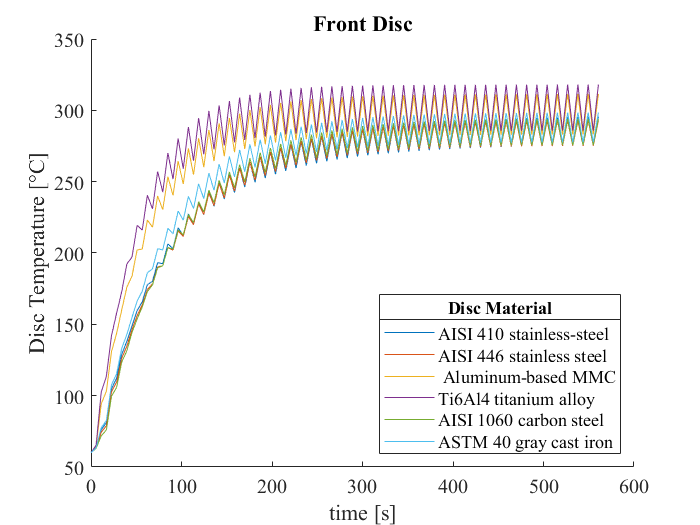

hold on
plot(time,T_disc_mat(1,:)-273.15)
plot(time,T_disc_mat(2,:)-273.15)
plot(time,T_disc_mat(3,:)-273.15)
plot(time,T_disc_mat(4,:)-273.15)
plot(time,T_disc_mat(5,:)-273.15)
plot(time,T_disc_mat(6,:)-273.15)

% Formatting
set(gca, 'FontName', 'Times','fontsize',12)
xlabel('time [s]'),ylabel('Disc Temperature [°C]'), title('Front Disc')
hleg=legend('AISI 410 stainless-steel','AISI 446 stainless steel',...
        ' Aluminum-based MMC','Ti6Al4 titanium alloy','AISI 1060 carbon steel',...
        'ASTM 40 gray cast iron','location','southeast');
htitle = get(hleg,'Title');
set(htitle,'String','Disc Material')